# Evaluación 7.1

Alumno: Diego Garcia Rueda

**Objetivo: **Implementar un codigo que genere la trayecotia "D I E G" a partir del tiempoy de las velocidades angulares y lineares en un plano 2D.

### **Especificaciones de las funciones:**

Esta función es la encargada de realizar el movimiento definiendo las velocidades lineales y angulares a partir del numero de puntos, cada punto tiene una coordenada para el plano X y una para el plano Y.

El recorrido entre puntos ocurre mediante un iterados que va recorriendo el numero total de coordenadas (el numero total de puntos). Se determina el punto actual y el punto siguiente, se obtiene la diferencia de distancia entre ambos puntos en ambos ejes (xx, yy) ya que esto nos permitirá definir el angulo de giro y la distancia a recorrer en esa dirección.

El angulo se determina obteniendo el arcotangente entre los 2 puntos, mientras que la distancia se obtiene mediante el teormea de Pitagoras, obteniendo asi la distancia  entre ambos puntos.

Toda esta informacion se guarda en 2 arrays que almacenan los valores, en caso de que se este efectuando un giro, la velocidad lineal será de 0 mietras que en velocidad angular se establecerá el angulo necesario para girar.

En caso de que se este efectuando un desplazamiento, en velocidad angular habria un valor de 0 mientras que en la velocidad lineal se almacenaria la distancia a recorrer.

`function [v, w] = setSteps(coord_x, coord_y)`

`    % Inicializar las variables de posición y ángulo`

`    px = 0; % coordenada x previa`

`    py = 0; % coordenada y previa`

`    th = 0; % ángulo previo`

`    % Inicializar los vectores de velocidades`

`    v = []; % velocidad lineal`

`    w = []; % velocidad angular`

`    % Iterar a través de los puntos en la trayectoria`

`    for pts = 1:length(coord_x)`

`        x = coord_x(pts);`

`        y = coord_y(pts);`

`        xx = x-px;`

`        yy = y-py;`

`        px = x;`

`        py = y;`

`        % Calcular la dirección del siguiente segmento de la trayectoria`

`        buffer = atan2(yy, xx);`

`        % ángulo entre el segmento y la dirección actual`

`        real_th = buffer - th; `

`        th = buffer;`

`        % Velocidades lineal y angular necesarias para girar hacia el siguiente segmento`

`        w = [w, real_th * ones(1, 10)];`

`        v = [v,       0 * ones(1, 10)];`

`        % Velocidades lineal y angular necesarias para avanzar en el siguiente segmento`

`        ds = sqrt(xx^2 + yy^2);`

`        w = [w,  0 * ones(1, 10)];`

`        v = [v, ds * ones(1, 10)];`

`    end`

`    % Agregar una velocidad lineal y angular final de cero para detener el robot`

`    w = [w, 0*ones(1, 10)];`

`    v = [v, 0*ones(1, 10)];`

`end`

Esta función es la encargada de ejecutar el ambiente virtual para la simulación definiendo todos los parametros para poder realizarla. Rcibe como parametro:

**f**`unction plotRobot(N, x, y, phi, hx, hy, xmn, xmx, ymn, ymx)`

`    %%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%    `

`    % a) Configuracion de escena`

`    ts = 0.001;`

`    scene=figure;  % Crear figura (Escena)`

`    set(scene,'Color','white'); % Color del fondo de la escena`

`    set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas`

`    sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador`

`    set(scene,'position',sizeScreen); % Configurar tamaño de la figura`

`    camlight('headlight'); % Luz para la escena`

`    axis equal; % Establece la relación de aspecto `

`    grid on; % Mostrar líneas de cuadrícula en los ejes`

`    box on; % Mostrar contorno de ejes`

`    xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje`

`    view([-0.1 35]); % Orientacion de la figura`

`    axis([xmn xmx ymn ymx 0 1]); % Ingresar limites minimos y maximos en los ejes x y z `

`    scale = 2;`

`    MobileRobot;`

`    H1=MobilePlot(x(1),y(1),phi(1),scale);hold on;`

`    H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);`

`    for k=1:N`

`        delete(H1);    `

`        delete(H2);   `

`        H1=MobilePlot(x(k),y(k),phi(k),scale);`

`        H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);`

`    end`

`end`

La siguiente función es la encargada de realizar la cinemática del robot utilizando al Uniciclo usando los valores de angulo a girar y distancia a desplazarse.

`function  MobileRobot`

`load('Uniciclo.mat')`

`global Uniciclo;`

`% 1 m de largo.`

`% 0.5 m de ancho`

`Uniciclo.structureVertices=structure.vertices';`

`Uniciclo.structureFaces=structure.faces;`

`Uniciclo.motorVertices=motor.vertices';`

`Uniciclo.motorFaces=motor.faces;`

`Uniciclo.wheelVertices=wheel.vertices';`

`Uniciclo.wheelFaces=wheel.faces;`

`Uniciclo.baseWheelVertices=baseWheel.vertices';`

`Uniciclo.baseWheelFaces=baseWheel.faces;`

`Uniciclo.wheelCastorVertices=wheelCastor.vertices';`

`Uniciclo.wheelCastorFaces=wheelCastor.faces;`

`Uniciclo. baseCastorVertices=baseCastor.vertices';`

`Uniciclo.baseCastorFaces=baseCastor.faces;`

### `Ejecución del código:`

Se ejecuta el codigo utilizando todas las funciones anteriores. Lo primero que se realiza es determinar la trayectoria que se debe seguir incluyendo los waypoints deseados para satisfacer esta trayectoria, Posteriormente se obtienen los angulos de giros y las distancias a recorrer

%Calculo de trayectoria a partir de las coordenadas
%usamos un delta de tiempo de 1 segundo para cada paso en coordenada.

coord_x_1 = [1, 0, 0, 1, 2, 2, 1, 2.5, 2.5, 5, 3, 3,   5,   3,   3, 5, 5.5, 5.5, 7.5, 5.5, 5.5, 7.5, 7.5, 6.5];
coord_y_1 = [0, 0, 3, 3, 2, 1, 0, 0,   3,   3, 3, 1.5, 1.5, 1.5, 0, 0, 0,   3,   3,   3,   0,   0,   1,   1];

%Se llama la función de calculo de angulo de giro y distancia
[v, w] = setSteps(coord_x_1, coord_y_1)

v =      0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0


w =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416         0         0         0         0         0         0         0         0         0         0   -1.5708   -1.5708   -1.5708   -1.5708   -1.5708   -1.5708   -1.5708   -1.5708   -1.5708   -1.5708


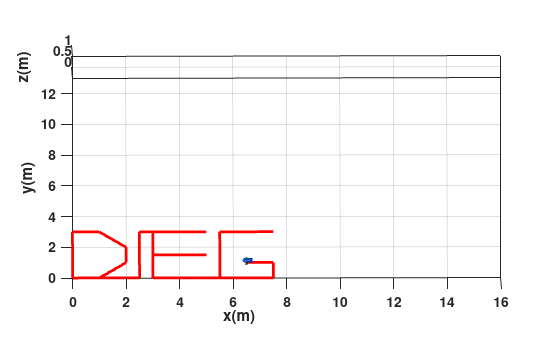


%Función para el calulo cinematico del movimiento del robot
[N, x, y, phi, hx, hy] = cinematicMobile(v, w);

%Plot de la trayectoria
plotRobot(N, x, y, phi, hx, hy, 0, 16, 0, 13)

### **Respuestas a las preguntas**

**a) ¿Cuál fue el o los parametros que se modifican para obtener una trayectoria recta? ¿Por qué?**

En este caso, al utilizar waypoints todas as trayectorias que se usan son rectas, se selcciona un punto de partida y un punto de llegada, estos fueron declarados en los vectores de coordenadas, se tiene que declarar a que posición se desea llegar, en base a estas coordenadas se establece si es que el robot tiene que modificar su orientación para llegar al nuevo punto y con esto se puede determinar la distancia que tiene que recorrer para llegar al objetivo.

Al avanzar en una trayuectoria recta la velocidad lineal del robot se modifica, de la misma manera se modifica su posición, e este caso su posición en el eje X y el eje Y 

**b) ¿Cuál fue el o los parametros que se modifican para obtener una trayectoria curva? ¿Por qué?En este caso, al utilizar waypoints todas as trayectorias que se usan son rectas, se selcciona un punto de partida y un punto de llegada, estos fueron declarados en los vectores de coordenadas**

En este caso lo que modifique fue implementar una mayor cantidad de waypoints, esto permite generar una trayectoria más curva, ekl numero de waypoints incrementa pero la trayectoria puede apreciarse más definida, en la trayectoria mostrada anteriormente se puede observar un ejemplo de esto en la letra D, ya que a un mayor numero de waypoints se observa una mejor curva, hay que tener en cuenta que con esto el procesamiento será mas tardado y la trayectoria tardará algo más de tiempo en completarse. Al tener mas waypoints cambian tanto como la velocidad lineeal al avanzar o detenerse al llegar a cada punto de la trayecrotia para posteriormente modificarse la velocidad angular del robot cuando se encuentre girando.

**c) ¿Cuál fue el o los parametros que se modifican para obtener un giro? ¿Por qué?**

En el giro se modifica la velocidad angular del robot, esta va cambiando dependiendo de que se requiera una rotación paara seguir con la trayectoria.

**d) ¿Que papel desempeña  el vector de tiempo en la generación de la trayectoria?**

El vector de tiempo en este caso ayudaba como medida de muestreo, en la funcion "cinematicMobile" podia usar este diferencial para determinar el avance lineal al momento de los desplazamientos, y al determianr el nuevo angulo de orientación al que se encuentra el robot.

Al girar el robot se usaba este diferencial para determinar la nueva orientación, posteriormente al obtener los componentes de la distancia a recorrer (x, y), estos componentes se multiplicaban por el diferencial de tiempo para asi conocer la nueva posicion del robot dependiendo el tiempo (hx, hy) basicamente el tiempo funcina como muestreo.

**e) ¿Cuales fueron los parametros que se ajustaron para obtener las dimensiones de las trayectorias deseadas?**

En este caso al usar waypoints fue que pude determinar las dimensiones que deseaba unicamente modificando las coordenadas en el eje X y en e eje Y, permitiendome de esta manera configurár a mano cuales serián las dimensiones de las letras a mi parecer.